clear all
close all
addpath(genpath('/data/drive/postdoc/talks/labmeeting_Bayes_march2020/models/dev'));
addpath(genpath('~/tools/matlab/shared_functions'))
iter = 10;
domain = 0; % 0 = positive domain; -1 = negative domain   
ncues = 3;
noparams = 2;
clear('out', 'C')
params = {'lambda_ch', 'lambda_noch'};
noruns = 3;

D = [];
for nr = 1:noruns
    limits= [0 10; 0 10];
    t = 1;
    for lamb_ch1 = 0:2:10
        for lamb_ch0 = 0:2:10
            D.true(nr, t,1) = lamb_ch1;
            D.true(nr, t,2) = lamb_ch0;
            % Generate distributions of rewards
            n = 120;
            % data
            d=[];
            d.cookies_morning = 30+7*randn(1,n);
            d.ch_present      = binornd(zeros(1,n)+1, 0.5);
            d.h               = 8;
            
            % use current parameter combination to generate time series
            o = m1(D.true(nr, t, :), d)
            d.cookies_evening = o.pred_cookies_evening;
            
            % fit model
            
            for i = 1:noparams %SPECIFIED to 3 params
                while true
                    initial_val(i) = rand * limits(i,2);
                    if initial_val(i) > limits(i,1) && initial_val(i) < limits(i,2)
                        break
                    end
                end
            end
            
            lb = limits(:,1)';
            ub = limits(:,2)';
            
            
            X0(1:noparams) = initial_val;
 
            [X, err] = bads(@m1_error, X0, lb, ub, [], [], [], [], d);
            D.err(nr) = err;
            D.est(nr, t,:) = X;
           
         t = t+1;
        end
    end
end

o = struct with fields:
    pred_cookies_evening: [1×120 double]


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2         18.4597               1                              Uncertainty test
     0           4          18.386               1            Initial mesh      
     1           6          18.386             0.5             Refine grid      Train (failed)
     2           7        -3.17541             0.5    Successful search (ES-wcm)      
     2          16        -3.17541            0.25             Refine grid      Train
     3          22        -3.17541           0.125             Refine grid      
     4          28        -3.17541          0.0625             Refine grid      
     5          34        -3.17541        0.015625             Refine grid      
     6          40        -3.17541      0.00390625             Refine grid      

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Fun

o = struct with fields:
    pred_cookies_evening: [1×120 double]


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2         6.84364               1                              Uncertainty test
     0           4        -1.09318               1            Initial mesh      
     1           6        -1.09318             0.5             Refine grid      Train
     2           8        -2.33916             0.5    Successful search (ES-wcm)      
     2           9        -2.34406             0.5    Incremental search (ES-ell)      
     2          16        -2.38191            0.25             Refine grid      Train
     3          23        -2.64075             0.5         Successful poll      
     4          28        -2.64075            0.25             Refine grid      
     5          33        -2.64075           0.125             Refine grid      
     6          35        -2.74939           0.125    Successful search (ES-wcm)      

o = struct with fields:
    pred_cookies_evening: [1×120 double]


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -2.34721               1                              Uncertainty test
     0           4        -2.34721               1            Initial mesh      
     1           6        -2.34721             0.5             Refine grid      Train
     2          13        -2.34721            0.25             Refine grid      
     3          15        -2.37368            0.25    Incremental search (ES-wcm)      
     3          21        -2.37368           0.125             Refine grid      
     4          23        -2.57187           0.125    Successful search (ES-ell)      
     4          25         -2.5768           0.125    Incremental search (ES-wcm)      
     4          27        -2.57738           0.125    Incremental search (ES-ell)      
     4          33        -2.57738          0.0625             Refine grid   


save(['m1_' num2str(noruns) 'runs.mat']);

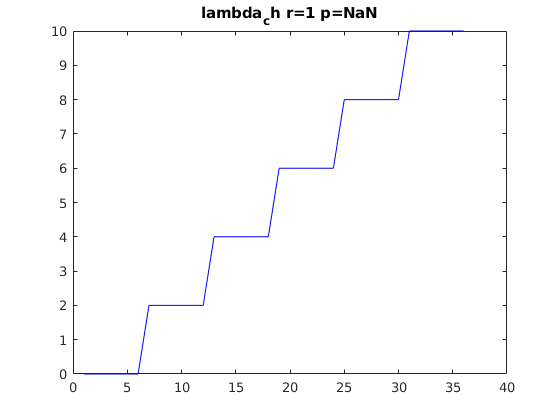

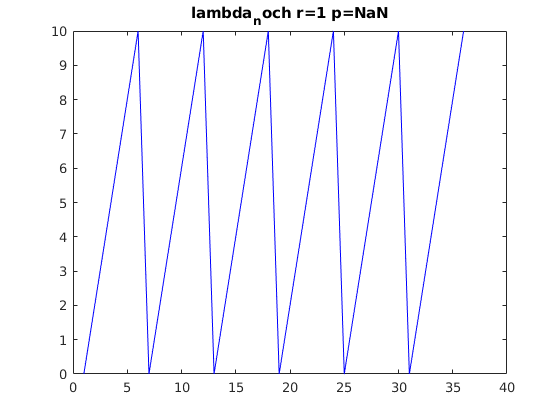

load(['m1_' num2str(noruns) 'runs.mat']);
minerr  = find(D.err==min(D.err));
for np = 1:noparams
    A = [squeeze(D.true(minerr,:,np))' squeeze(D.est(minerr,:,np))'];
    [rr, pp] = corr(A(:,1), A(:,2));    
    f=figure;
    plot(A(:,1), 'Color', 'r');
    hold on 
    plot(A(:,2), 'Color', 'b');
    %legend({'true', 'estimated'});
    title([params{np} ' r=' num2str(round(rr,3)), ' p=' num2str(round(pp,3))]);
end

load(['m1_' num2str(noruns) 'runs.mat']);
minerr  = find(D.err==min(D.err));
minerr = minerr(1)

minerr = 1

A = [squeeze(D.est(minerr,:,:))];
[R,P] = corrcoef(A)

R =     1.0000   -0.0133
   -0.0133    1.0000


P =     1.0000    0.9385
    0.9385    1.0000


f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


'corrplot' requires Econometrics Toolbox.